# Process Identification of an ARX Model

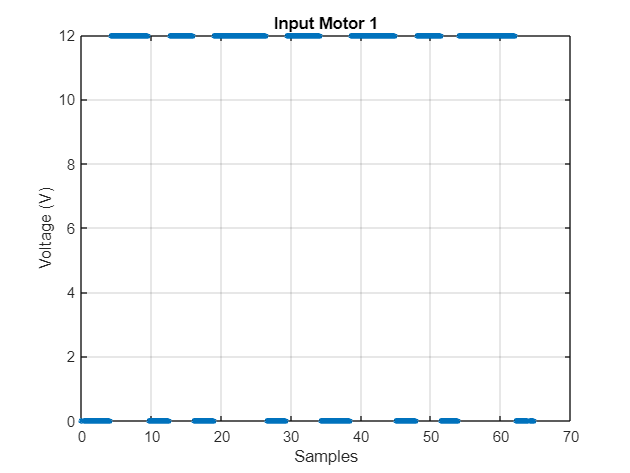

Data = xlsread("C:\Users\eugen\Downloads\plot_data.csv");

t = Data(:,1);
U = Data(:,3);
Y_1 = Data(:,4);


plot(t,U,'*','MarkerSize',4)
title('Input Motor 1');
ylabel('Voltage (V)');
xlabel('Samples');
grid on

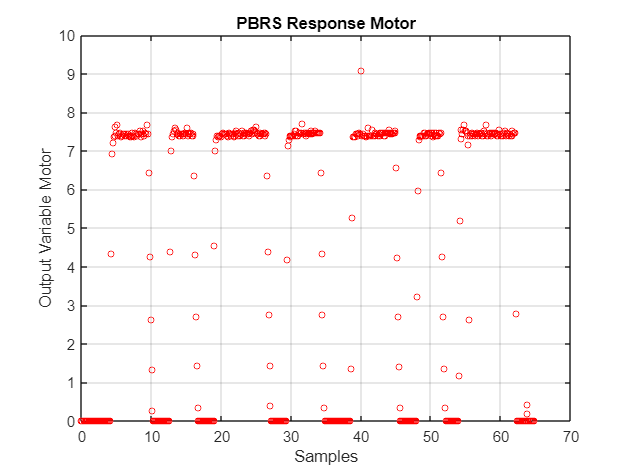


plot(t,Y_1,'o r', 'MarkerSize', 4)
title('PBRS Response Motor')
ylabel('Output Variable Motor')
xlabel('Samples')
grid on

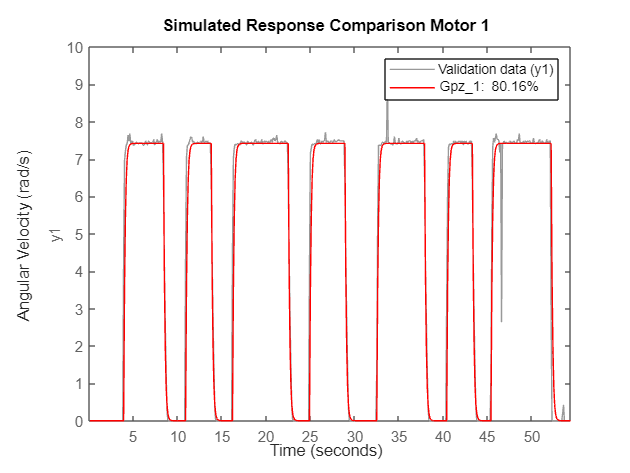


% Motor 1

N = length(Y_1);

%
X=[-[0;Y_1(1:N-1)], -[0;0;Y_1(1:N-2)], [0;U(1:N-1)],[0;0;U(1:N-2)], [0;0;0;U(1:N-3)]];

%Covariance Matrix
Q = X'*X;

%Vector of parameters
Theta = inv(Q)*X'*Y_1;

a1 = Theta(1);
a2 = Theta(2);
b0 = Theta(3);
b1 = Theta(4);
b2 = Theta(5);

z = tf('z', 0.1);
Gpz_1 = ((b0*z^(2)+b1*z+b2)/(z^2+a1*z+a2))*z^(-1);

compare_data_1 = iddata(Y_1, U, 0.1);
compare(compare_data_1, Gpz_1,'r');
title('Simulated Response Comparison Motor 1')
ylabel('Angular Velocity (rad/s)')

Ymodel_1 = predict(Gpz_1,compare_data_1);


% Motor 1 
%Covariance in the measurments
fprintf('\n Motor 1:')


 Motor 1:

Gpz_1

Gpz_1 =
 
  0.2918 z^2 - 0.02748 z + 0.01179
  --------------------------------
    z^3 - 0.6419 z^2 + 0.08843 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Sy_1 = sum((Y_1-mean(Y_1)).^2)

Sy_1 = 6.7353e+03

Sr_1 = sum((Y_1-Ymodel_1.OutputData).^2)

Sr_1 = 265.0810

R2_1 = (Sy_1 - Sr_1)/Sy_1

R2_1 = 0.9606